# Task 1 - Single Gaussian

clc
clear all
[training_set, testing_set, vowel_code, talker_group_code, talker_number, vowel_classes] = prepare_data();

## (a) Class means and covariance matrices.

class_means = get_mean(training_set, vowel_code);
class_covariances = get_cov(training_set, vowel_code);

## (b) Classify with full covariance matrix

targets = get_targets(testing_set, vowel_classes);

targets =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


targets =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


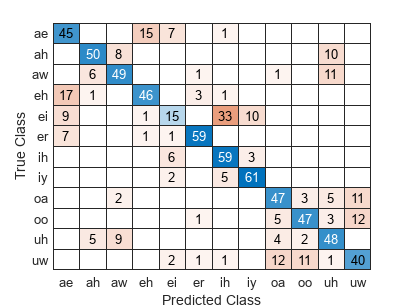

predicted_classes = map_classifier(testing_set, class_means, class_covariances)';
cm = confusionmat(targets, predicted_classes);
confusionchart(cm, string(vowel_classes))
saveas(gca, "figs/confmat_fullcov.png")

## (c) Classify with diagonal covariance matrix

for i = 1:size(class_covariances, 3)
    class_covariances(:,:,i) = class_covariances(:,:,i).*eye(3);
end
targets = get_targets(testing_set, vowel_classes);
predicted_classes = map_classifier(testing_set, class_means, class_covariances)';
cm = confusionmat(targets, predicted_classes);
confusionchart(cm, string(vowel_classes))
saveas(gca, "figs/confmat_diagcov.png")